# **Acoustic Signal Partitioning in Wren-Warblers**

**Simple methods to analyze multispecies bio-acoustic datasets (using Raven Pro and MATLAB2019b)**

Sample dataset: comprises of multiple notes labelled in Raven Pro (Cornell Lab of Ornithology) for four species of Wren-Warblers (genus *Prinia*)

*Note:* the analysis is non phylogenetic due to the absence of phylogeny for *Prinia *species

Parameters measured:

- Average Entropy (AE)

- Begin Time (BT)

- End Time (ET)

- 90% Bandwidth (BW)

- Center Frequency (CF)

- Delta Time ($\Delta t$) (DT)

- Highest Frequency (HF)

- Lowest Frequency (LF)

- Mean Peak Frequency (PF)

- Maximum Peak Frequency (MPFC)

- Minimum Peak Frequency (mPFC)

- Peak Frequency Contour (PFC)

Labels:

- Song/Call (SC)

- Good Label (GL) (Based on signal to noise ratio in spectrogram)

- *Prinia* Species (P)

- Note Type (NT) - arbitrarily hand labelled and visually clustered

Four Prinia Species:

- Ashy Prinia (represented by $A$ or $a$)

- Grey Breasted Prinia (represented as $G$ or $g$)

- Plain Prinia (represented as $P$ or $p$)

- Jungle Prinia (represented as $J$ or $j$)

*Note:* PFC captures the 'shape' of the note. The first and last values of the PFC contour are a good representation of whether the signal is an upsweep, a downsweep etc.

#### Import Dataset

The .mat file contains the raw parameters as variables.

$N = 5472$ (total number of notes labelled)

load('sample_dataset_prinia_project.mat')

We need to construct a raw data variable with the parameters we want to use to construct the acoustic space (in this case 9 parameters - Average Entropy, Bandwidth 90%, Center Frequency, Delta Time, Peak Frequency (Mean Peak Frequency), Peak Frequency Contour Start, Peak Frequency Contour End, Peak Frequency Contour Maximum, Peak Frequency Contour Minimum

vbls = {'Average Entropy','Bandwidth 90%','Center Frequency','Delta Time','Peak Frequency','PFC start','PFC end', 'PFC Max', 'PFC Min'};
[PFCs,PFCe] = firstlast(PFC);
raw_acoustic_data = [AE, BW, CF, DT, PF, PFCs, PFCe, PFCM, PFCm];

Create integer prinia labels $A$-1, $G$-2, $J$-3, $P$-4

Pn = ones(size(P));
Pn(ismember(P,'A')) = 1; Pn(ismember(P,'G')) = 2; Pn(ismember(P,'J')) = 3; Pn(ismember(P,'P')) = 4;

Labelled data can be used to perform a LDA (Linear Discriminant Analysis)

labelled_acoustic_data = [raw_acoustic_data Pn];

#### Seperate dataset into song data and call data

[labelled_song_data, songP, songNT] = song(labelled_acoustic_data, SC, GL, P, NT);

Due to low sample size of call data we will not take into account 'goodness' of label, but instead consider all notes labelled as calls

labelled_call_data = labelled_acoustic_data(ismember(SC,'C'),:);


$$N_{song} = 4615\\
N_{call} = 429$$


#### Principal Component Analysis on Song Data

A PCA on the whole dataset will help us visualize the overlap in the song space

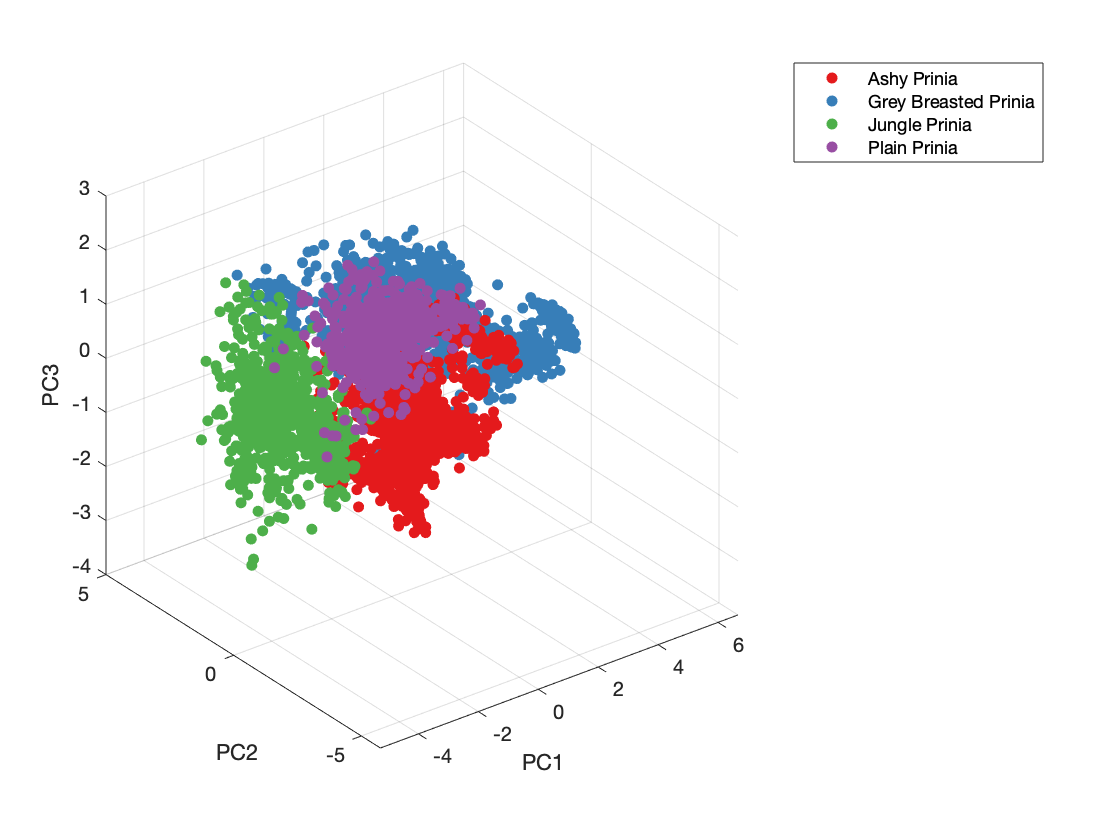

%get unlabelled song data
song_data = labelled_song_data(:,1:end-1);

%PCA on correlation matrix (equivalent to PCA on covariance matrix of normalized
%values)
[coeff, score, latent, expl] = pcacorr(song_data);

clf;
scoreplotter3d(score, labelled_song_data(:,end), {'Ashy Prinia', 'Grey Breasted Prinia', 'Jungle Prinia', 'Plain Prinia'});
hold off;

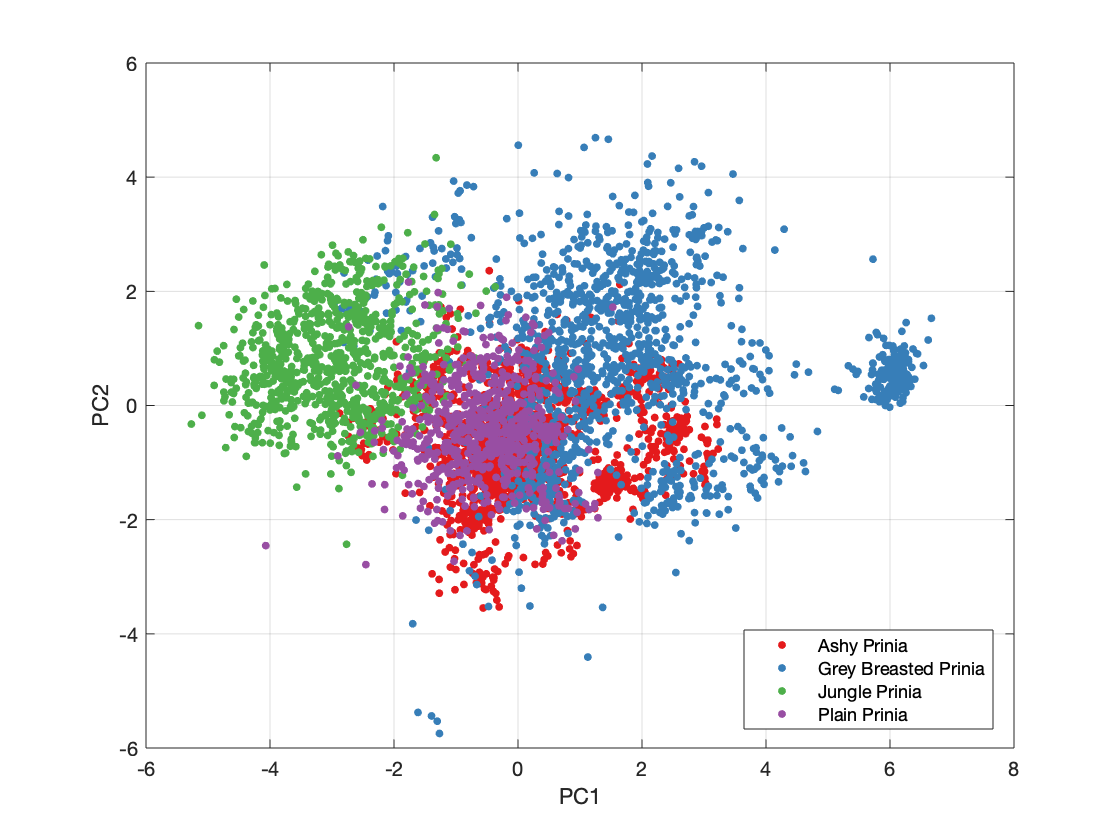

%2d visualisation
colors = brewermap(4,'Set1');
gscatter(score(:,1),score(:,2),labelled_song_data(:,end),colors,".",10);
grid on; legend({'Ashy Prinia','Grey Breasted Prinia', 'Jungle Prinia', 'Plain Prinia'});
xlabel('PC1'); ylabel('PC2');

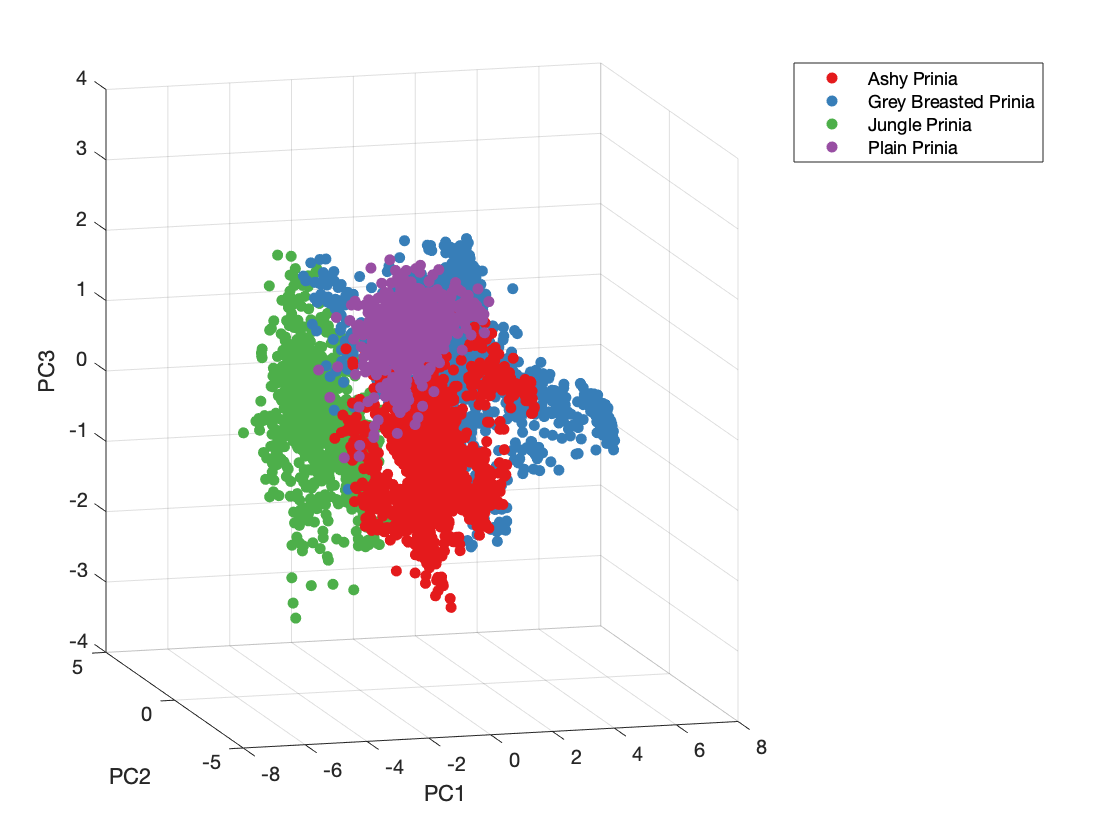

%making a video of a 3D PC space for visualizing overlap better
clf; figure(1);
scoreplotter3d(score, labelled_song_data(:,end), {'Ashy Prinia', 'Grey Breasted Prinia', 'Jungle Prinia', 'Plain Prinia'});
xlim([-8 8])
ylim([-5 5])
zlim([-4 4])
%change figure limits to suit visualization
OptionZ.FrameRate=15;OptionZ.Duration=5.5;OptionZ.Periodic=true;
CaptureFigVid([-20,10;-110,10;-190,80;-290,10;-380,10],'song_space_video',OptionZ);

%the video will be saved in current directory

#### Linear Discriminant Analysis on Song Data

A linear discriminant analysis on the whole dataset helps us identify overlap in parameters between the four species. 

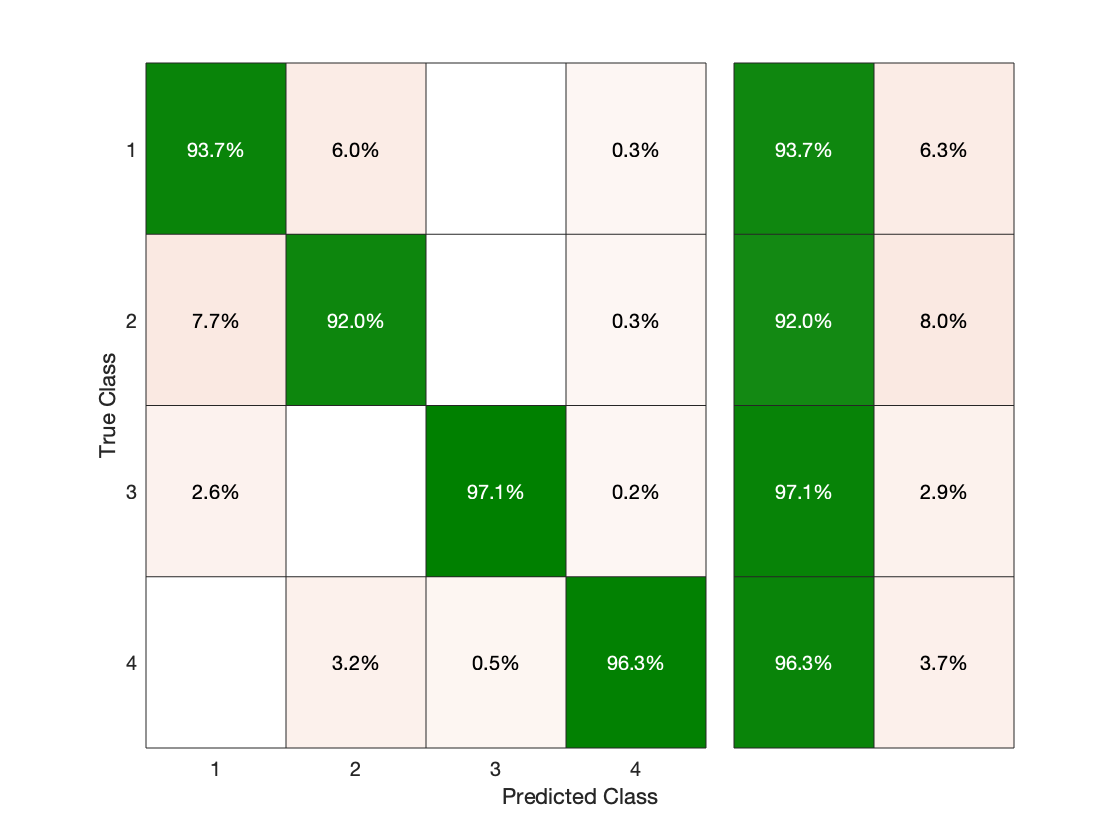

%k-fold cross validation with k = 10
k = 10;
[y_fit,accuracy] = LDClassifier(labelled_song_data,k);
confusionchart(labelled_song_data(:,end),y_fit,'DiagonalColor',...
    [0 0.5 0],"RowSummary","row-normalized",'Normalization',"row-normalized");

%note that the confusion matrix is row normalized
accuracy

accuracy = 0.9417

Shows that song space is highly partitioned.

**Null Model Analysis on Song Data**

A null model can be constructed by randomly sampling points from the PC axes. The null hypothesis is that the average interspecific (euclidena) distance in the observed dataset will equal the average interspecific distance in the null model.

%generating scorea, scoreg, scorej, scorep
scorea = score(labelled_song_data(:,end)==1,:); scoreg = score(labelled_song_data(:,end)==2,:); ...
    scorej = score(labelled_song_data(:,end)==3,:); scorep = score(labelled_song_data(:,end)==4,:);

%fit PC axes to normal distributions
PC_1_fit = fitdist(score(:,1),'Normal'); PC_2_fit = fitdist(score(:,2),'Normal'); PC_3_fit = fitdist(score(:,3),'Normal'); PC_4_fit = fitdist(score(:,4),'Normal'); ...
    PC_5_fit = fitdist(score(:,5),'Normal'); PC_6_fit = fitdist(score(:,6),'Normal'); PC_7_fit = fitdist(score(:,7),'Normal'); PC_8_fit = fitdist(score(:,8),'Normal'); ...
    PC_9_fit = fitdist(score(:,9),'Normal');
%verify that each PC is actually normally distributed (done at end)

n = 9; %3

scorea = scorea(:,1:n);
scoreg = scoreg(:,1:n);
scorej = scorej(:,1:n);
scorep = scorep(:,1:n);

%for experimental dataset
mean_ag = mean2(pdist2(scorea, scoreg, 'euclidean'))

mean_ag = 4.1882

mean_ap = mean2(pdist2(scorea, scorep, 'euclidean'))

mean_ap = 3.3059

mean_aj = mean2(pdist2(scorea, scorej, 'euclidean'))

mean_aj = 4.4053

mean_gp = mean2(pdist2(scoreg, scorep, 'euclidean'))

mean_gp = 4.2141

mean_gj = mean2(pdist2(scoreg, scorej, 'euclidean'))

mean_gj = 5.9129

mean_jp = mean2(pdist2(scorej, scorep, 'euclidean'))

mean_jp = 4.0439

mean_dist_obs = (mean_ag+mean_ap+mean_aj+mean_gp+mean_gj+mean_jp)/6

mean_dist_obs = 4.3450

**Randomization by pulling values from normal distributions fit to PC axes**

N_r = 500; %No. of randomizations

mean_dist = zeros(N_r,1);
mean_dist_ag = zeros(N_r,1);
mean_dist_ap = zeros(N_r,1);
mean_dist_aj = zeros(N_r,1);
mean_dist_gp = zeros(N_r,1);
mean_dist_gj = zeros(N_r,1);
mean_dist_jp = zeros(N_r,1);

for i = 1:N_r
    %generate random dataset
    score_gen = rand(4615,9);
    score_gen(:,1) = random(PC_1_fit,[4615,1]);
    score_gen(:,2) = random(PC_2_fit,[4615,1]);
    score_gen(:,3) = random(PC_3_fit,[4615,1]);
    score_gen(:,4) = random(PC_4_fit,[4615,1]);
    score_gen(:,5) = random(PC_5_fit,[4615,1]);
    score_gen(:,6) = random(PC_6_fit,[4615,1]);
    score_gen(:,7) = random(PC_7_fit,[4615,1]);
    score_gen(:,8) = random(PC_8_fit,[4615,1]);
    score_gen(:,9) = random(PC_9_fit,[4615,1]);
    score_gen = score_gen(:,1:n);

    score_type = zeros(4615,1);
    score_type(1:1799) = 1;
    score_type(1800:3155) = 2;
    score_type(3156:3962) = 3;
    score_type(3963:4615) = 4;

    score_type = score_type(randperm(length(score_type)));

    score_gena = score_gen(score_type == 1);
    score_geng = score_gen(score_type == 2);
    score_genj = score_gen(score_type == 3);
    score_genp = score_gen(score_type == 4);

    mean_ag = mean2(pdist2(score_gena, score_geng, 'euclidean'));
    mean_ap = mean2(pdist2(score_gena, score_genp, 'euclidean'));
    mean_aj = mean2(pdist2(score_gena, score_genj, 'euclidean'));
    mean_gp = mean2(pdist2(score_geng, score_genp, 'euclidean'));
    mean_gj = mean2(pdist2(score_geng, score_genj, 'euclidean'));
    mean_jp = mean2(pdist2(score_genj, score_genp, 'euclidean'));
    mean_dist_ag(i,1) = mean_ag;
    mean_dist_ap(i,1) = mean_ap;
    mean_dist_aj(i,1) = mean_aj;
    mean_dist_gp(i,1) = mean_gp;
    mean_dist_gj(i,1) = mean_gj;
    mean_dist_jp(i,1) = mean_jp;
    mean_dist(i,1) = (mean_ag+mean_ap+mean_aj+mean_gp+mean_gj+mean_jp)/6;
end

Sample Random Community

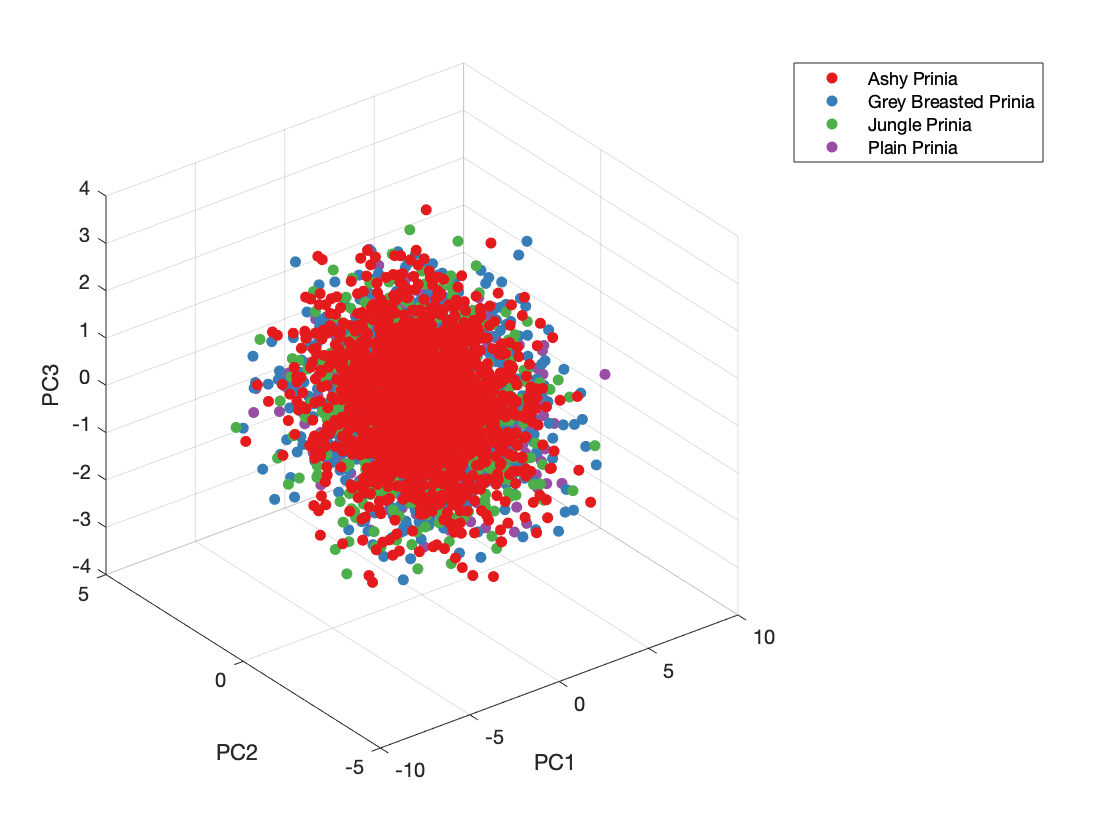

clf;
scoreplotter3d(score_gen,score_type,{'Ashy Prinia', 'Grey Breasted Prinia', 'Jungle Prinia', 'Plain Prinia'});

Compare randomly generated mean-distance distribution to observed mean distance 

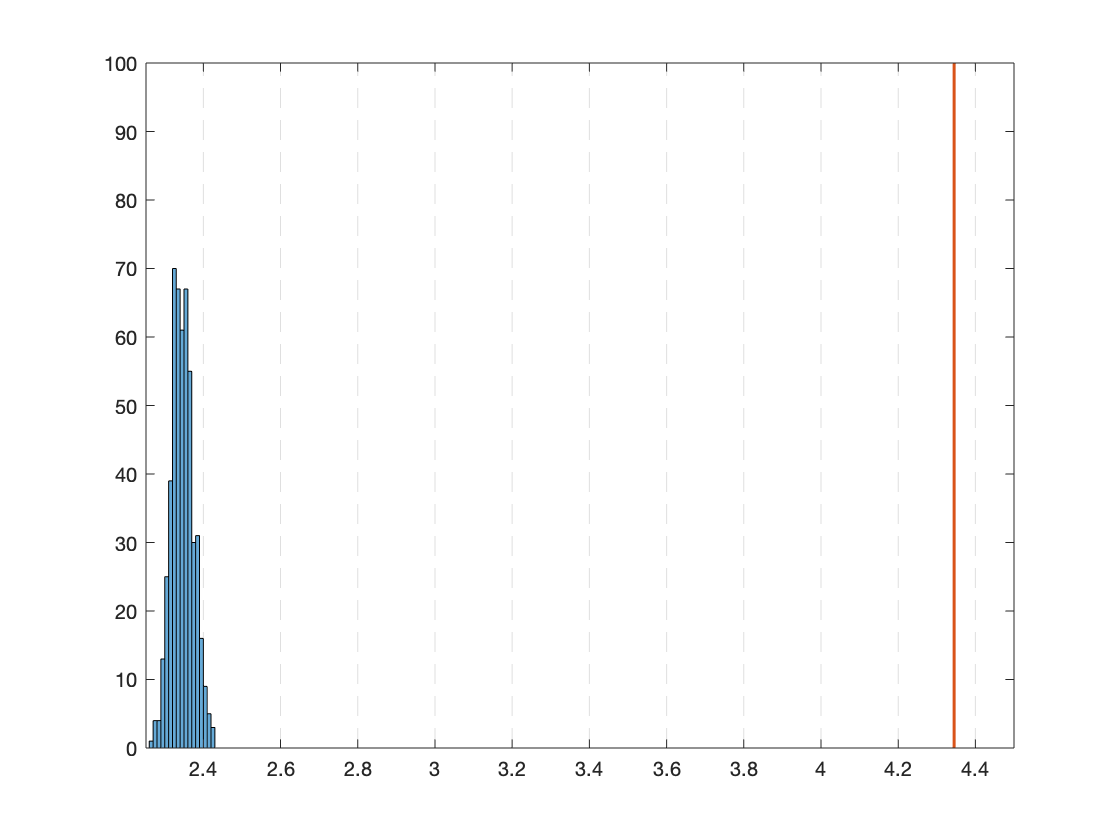

histogram(mean_dist) %mean_ag mean_ap mean_aj mean_gp mean_gj mean_jp
hold on;
y = 0:N_r/5;
x = mean_dist_obs.*ones(size(y));
plot(x,y,'LineWidth',1.5); hold off;
ax = gca;
ax.XGrid = 'on';
ax.GridLineStyle = '--';

m = mean(mean_dist); s = std(mean_dist);
Z = (mean_dist_obs-m)/s

Z = 70.9069

**Shuffling Analysis**

N_r = 500;
mean_dist = zeros(N_r,1);
mean_dist_ag = zeros(N_r,1);
mean_dist_ap = zeros(N_r,1);
mean_dist_aj = zeros(N_r,1);
mean_dist_gp = zeros(N_r,1);
mean_dist_gj = zeros(N_r,1);
mean_dist_jp = zeros(N_r,1);

for i = 1:N_r
    %generate random dataset
    score_gen = rand(4615,9);
    score_gen(:,1) = score(:,1);
    score_gen(:,2) = score(:,2);
    score_gen(:,3) = score(:,3);
    score_gen(:,4) = score(:,4);
    score_gen(:,5) = score(:,5);
    score_gen(:,6) = score(:,6);
    score_gen(:,7) = score(:,7);
    score_gen(:,8) = score(:,8);
    score_gen(:,9) = score(:,9);

    score_type = zeros(4615,1);
    score_type(1:1799) = 1;
    score_type(1800:3155) = 2;
    score_type(3156:3962) = 3;
    score_type(3963:4615) = 4;

    score_type = score_type(randperm(length(score_type)));

    score_gena = score_gen(score_type == 1);
    score_geng = score_gen(score_type == 2);
    score_genj = score_gen(score_type == 3);
    score_genp = score_gen(score_type == 4);

    mean_ag = mean2(pdist2(score_gena, score_geng, 'euclidean'));
    mean_ap = mean2(pdist2(score_gena, score_genp, 'euclidean'));
    mean_aj = mean2(pdist2(score_gena, score_genj, 'euclidean'));
    mean_gp = mean2(pdist2(score_geng, score_genp, 'euclidean'));
    mean_gj = mean2(pdist2(score_geng, score_genj, 'euclidean'));
    mean_jp = mean2(pdist2(score_genj, score_genp, 'euclidean'));
    mean_dist_ag(i,1) = mean_ag;
    mean_dist_ap(i,1) = mean_ap;
    mean_dist_aj(i,1) = mean_aj;
    mean_dist_gp(i,1) = mean_gp;
    mean_dist_gj(i,1) = mean_gj;
    mean_dist_jp(i,1) = mean_jp;
    mean_dist(i,1) = (mean_ag+mean_ap+mean_aj+mean_gp+mean_gj+mean_jp)/6;
end

Sample Shuffled Community

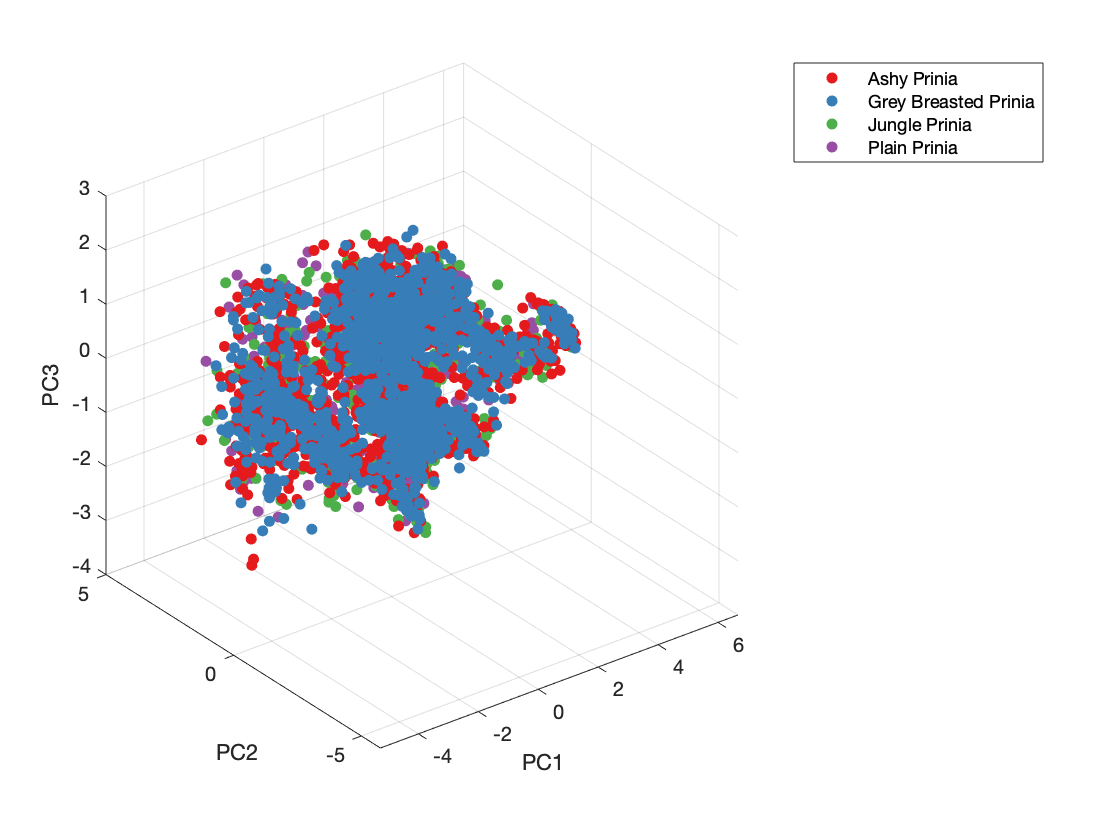

clf;
scoreplotter3d(score_gen,score_type,{'Ashy Prinia', 'Grey Breasted Prinia', 'Jungle Prinia', 'Plain Prinia'});

Compare mean-distance distribution generated by shuffling to observed mean distance 

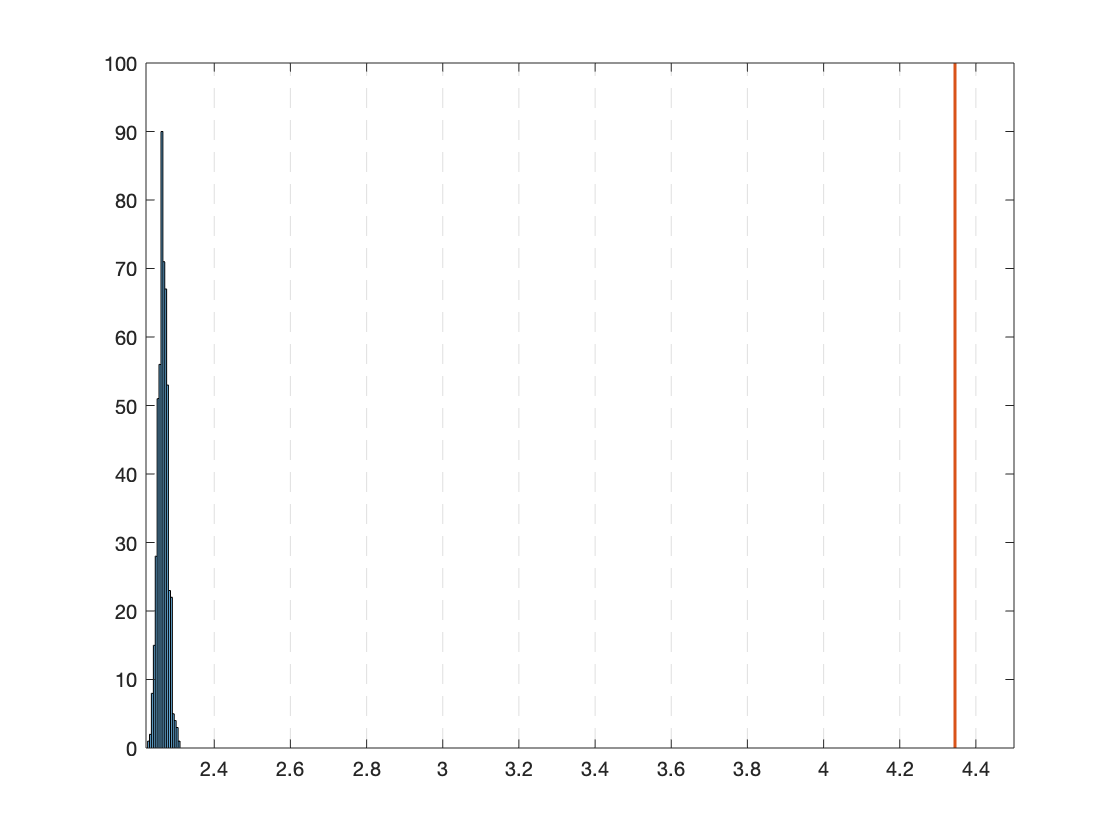

histogram(mean_dist) %mean_ag mean_ap mean_aj mean_gp mean_gj mean_jp
hold on;
y = 0:N_r/5;
x = mean_dist_obs.*ones(size(y));
plot(x,y,'LineWidth',1.5); hold off;
ax = gca;
ax.XGrid = 'on';
ax.GridLineStyle = '--';

m = mean(mean_dist); s = std(mean_dist);
Z = (mean_dist_obs-m)/s

Z = 164.2626

**Linear Discriminant Analysis on Call Data**

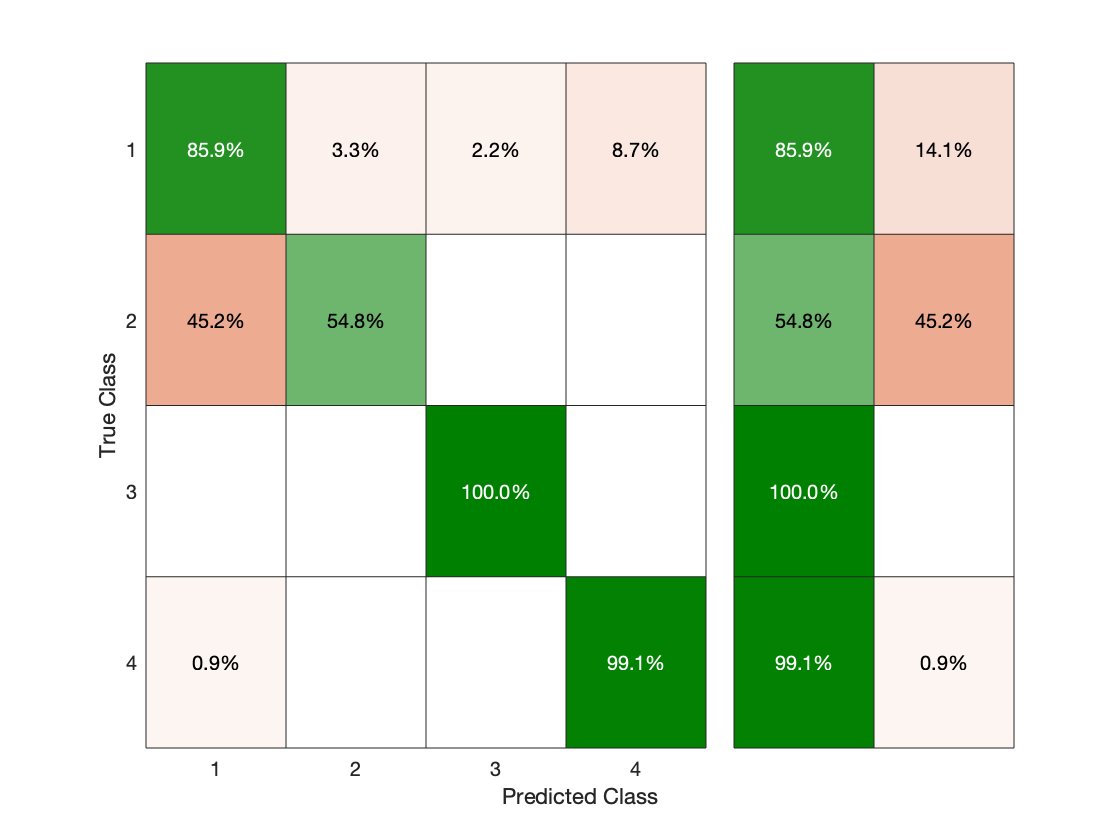

%k-fold cross validation with k  = 10
k = 10;
[y_fit,accuracy] = LDClassifier(labelled_call_data,k);
confusionchart(labelled_call_data(:,end),y_fit,'DiagonalColor',...
    [0 0.5 0],"RowSummary","row-normalized",'Normalization',"row-normalized");

accuracy

accuracy = 0.9207

Indicates overlap between Ashy and Grey Breasted Prinias

Verifying that the PC axes are normally distributed

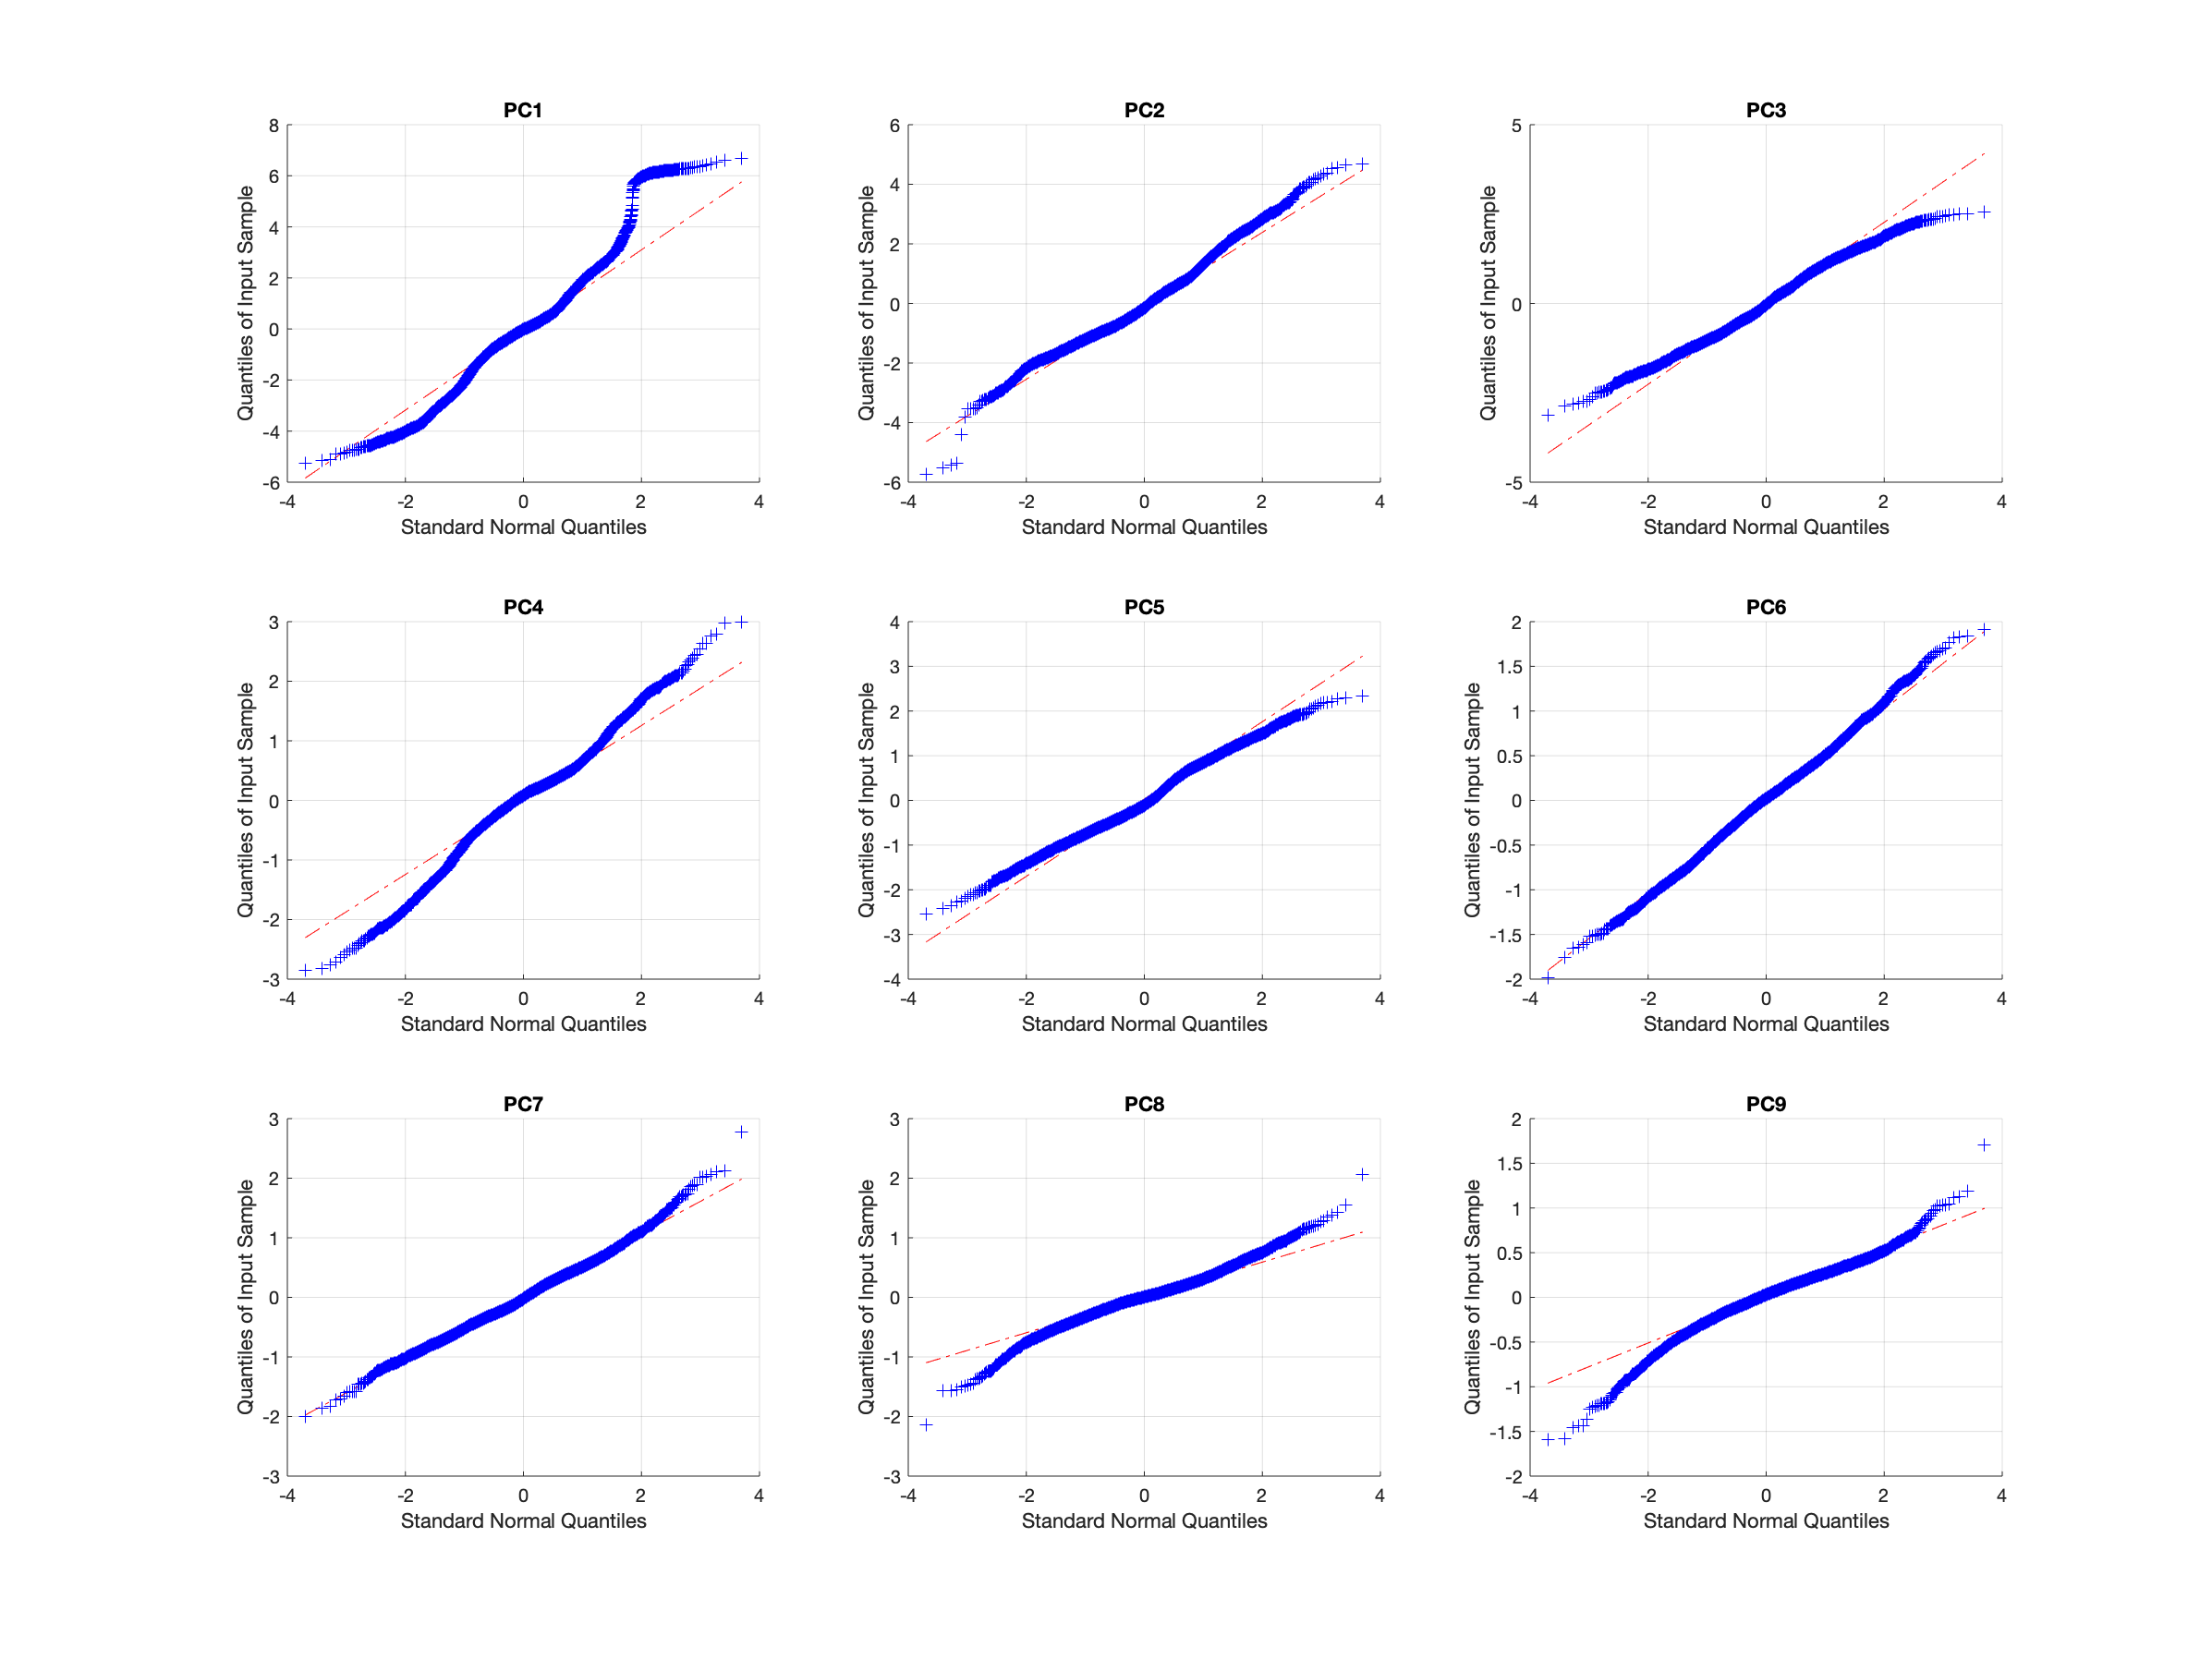

figure('Renderer', 'painters', 'Position', [10 10 1200 900])
for i = 1:9
    subplot(3,3,i)
    qqplot(score(:,i)); grid on;
    title(['PC' num2str(i)]);
end